Si se toman 1000 muestras de 100 datos cada una, la muestra generada por el dato i-esimos de cada muestra tambien va a ser de la misma distrubucion

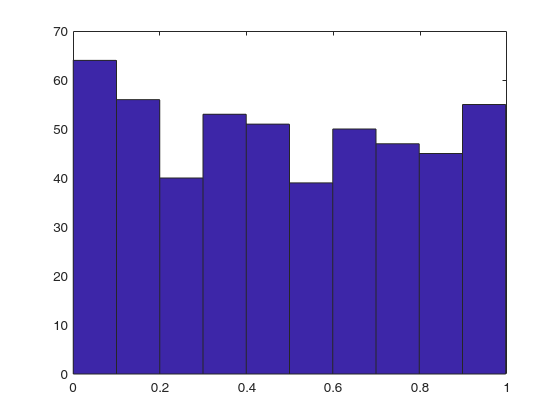

N=500;
n=100;
X=rand(N,n);
D1 = X(:,2);
hist(D1)

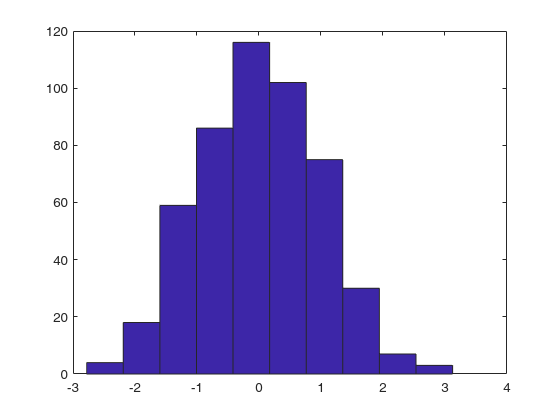

X=randn(N,n);
D1 = X(:,2);
hist(D1)

Lo mismo NO ocurre al tomar el mínimo

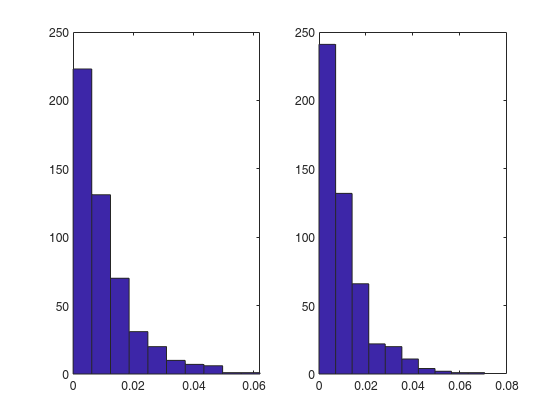

figure(1)
N=500;
n=100;
X=rand(N,n);
D1 = min(X');
hist(D1)

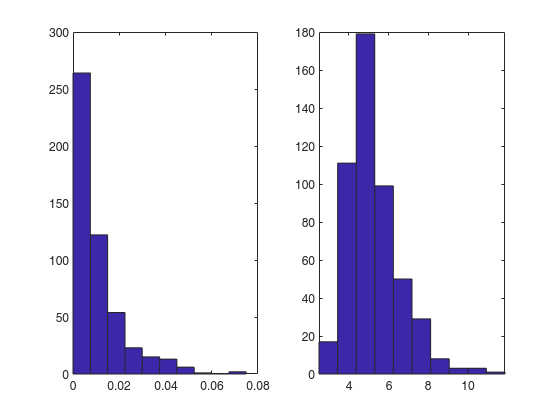

figure(2)
N=500;
n=100;
X=-log(rand(N,n));
D1 = min(X');
D2 = max(X');
subplot(1,2,1)
hist(D1)
subplot(1,2,2)
hist(D2)

Ahora veamos una estimación del mínimo para una uniforme entre 0 y 1 la media de este es 1/n+1

N=10000;
n=2; %esperemos que la media valga 0.333
X=rand(N,n);
D1 = min(X');
mean(D1)

ans = 0.3338

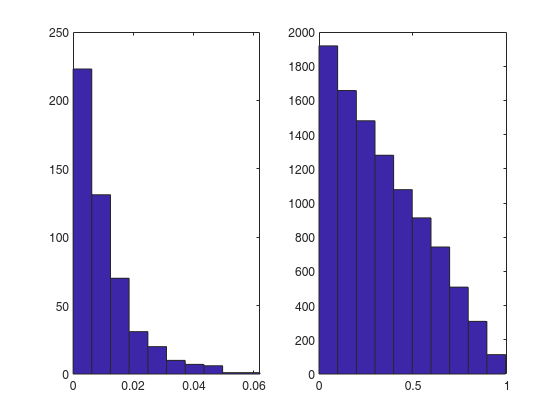

hist(D1)